# Parametry sygnałów

### Mateusz Wójcik, 12.12.2024

Laboratorium ma na celu zapoznanie się z podstawowymi parametrami sygnałów oraz metodami ich obliczania w środowisku MATLAB. W tym celu zapoznano się ze skryptem, w którym opisano poszczególne parametry, wykonano przykłady oraz odpowiednie zadania.

#### Wartość średnia

X=[1, 2, 3 4];
SREDNIA_X=mean(X) % 2.5000

SREDNIA_X = 2.5000

#### Średnia kwadratowa

X=[1, 2, 3];
RMS_X=rms(X) % sqrt((12+22+32)/3) 2.1602

RMS_X = 2.1602

#### Współczynnik szczytu

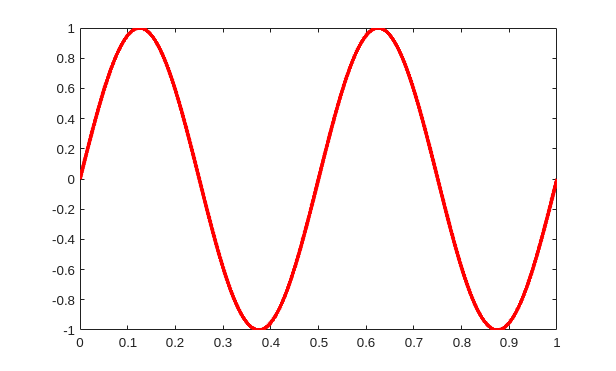

fs=5000;
t=0:(1/fs):1;
X=sin(2*pi*2*t);
plot(t, X, 'r', 'LineWidth', 3);

RMS_X=rms(X) % 0.7070

RMS_X = 0.7070

w=peak2rms(X) % 1.4144 (1/0.7070)= 1.4144

w = 1.4144

#### Współczynnik peak-to-peak

fs=5000;
t=0:(1/fs):1;
X=sin(2*pi*2*t);
plot(t, X, 'r', 'LineWidth', 3);

p2p=peak2peak(X) % 2

p2p = 2

#### Wartość minimalna i maksymakna

fs=5000;
t=0:(1/fs):1;
X=sin(2*pi*2*t);
plot(t, X, 'r', 'LineWidth', 3);

[a, b]=max(X)

a = 1

b = 626

[c, d]=min(X)

c = -1

d = 1876

#### Wariancja

X=[1, 2, 6];
a=var(X) % 7 bo wartosc oczekiwana = 3, wart_oczek=(1+2+6)/3

a = 7

% ((1-3)2+(2-3)2+(6-3)2)/2 = (4+1+9)/2=14/2=7
X=[1, 2, 9];
a=var(X) % 19 bo wartosc oczekiwana = 4, wart_oczek=(1+2+9)/3

a = 19

% ((1-4)2+(2-4)2+(9-4)2)/2 = (9+4+25)/2=19
X=[1, 2, 3, 4, 5];
a=var(X) % 2.5 bo wartosc oczekiwana = 3,

a = 2.5000

%((1-3)2+(2-3)2+(3-3)2+ (4-3)2+(5-3)2)/4 =
% =(4+1+0+1+4)/4=10/4=2.5

#### Odchylenie standardowe

X=[1, 2, 6];
stdX=std(X) % 2.6458 bo sqrt(7)= 2.6458

stdX = 2.6458

X=[1, 2, 9];
stdX=std(X) % 4.3589 bo sqrt(19)= 4.3589

stdX = 4.3589

X=[1, 2, 3, 4, 5];
stdX=std(X) % 1.5811 bo sqrt(2.5)= 1.5811

stdX = 1.5811

## Zad 1

Importowanie danych z plików .wav oraz wyliczanie dla nich średniej

X = [0, 1, 3];
[wiatrak_20, fs] = audioread("pliki_wav/wiatrak_20.wav");
[przekladnia, fs] = audioread("pliki_wav/przekladnia20.wav");
mean(X)

ans = 1.3333

mean(wiatrak_20)

ans = -2.4346e-05

mean(przekladnia)

ans = -4.2175e-04

## Zad 2

Obliczanie wartości RMS sygnałów:

rms(X)

ans = 1.8257

rms(wiatrak_20)

ans = 0.1855

rms(przekladnia)

ans = 0.1415

## Zad 3

Obliczanie współczynnika szczytu z sygnałów:

peak2rms(X)

ans = 1.6432

peak2rms(wiatrak_20)

ans = 4.2778

peak2rms(przekladnia)

ans = 4.7018

## Zad 4

Obliczanie wartości peak-to-peak sygnałów:

peak2peak(X)

ans = 3

peak2peak(wiatrak_20)

ans = 1.5757

peak2peak(przekladnia)

ans = 1.2662

## Zad 5

Obliczanie wartości minimalnej i maksymalnej sygnałów:

min(X)

ans = 0

max(X)

ans = 3

min(wiatrak_20)

ans = -0.7821

max(wiatrak_20)

ans = 0.7936

min(przekladnia)

ans = -0.6008

max(przekladnia)

ans = 0.6654

## Zad 6

Obliczanie wariancji sygnałów:

var(X)

ans = 2.3333

var(wiatrak_20)

ans = 0.0344

var(przekladnia)

ans = 0.0200

## Zad 7

Obliczanie odchylenia standardowego sygnałów:

std(X)

ans = 1.5275

std(wiatrak_20)

ans = 0.1855

std(przekladnia)

ans = 0.1415

### Zad 8

Obliczanie energii sygnałów:

sum(abs(X).^2)

ans = 10

sum(abs(wiatrak_20).^2)

ans = 1.5179e+03

sum(abs(przekladnia).^2)

ans = 883.1704

## Zad 9

Obliczanie średniej mocy sygnałów:

bandpower(X)

ans = 3.3333

bandpower(wiatrak_20)

ans = 0.0344

bandpower(przekladnia)

ans = 0.0200

## Zad 10

Obliczanie RSS z sygnałów:

rssq(X)

ans = 3.1623

rssq(wiatrak_20)

ans = 38.9602

rssq(przekladnia)

ans = 29.7182

## Zad 11

Zastosowanie funkcji **seqperiod**, która sprawdza, czy w danej kolumnie istnieje jakiś wzorzec, okresowość powtarzania się danych.

X1 = [4 0 1 6;
2 0 2 7;
4 0 1 5;
2 0 5 6];
seqperiod(X1)

ans =      2     1     4     3



X2 = [4 0 1 6;
2 0 2 7;
4 0 1 5;
2 0 5 6;
1 0 1 7];
seqperiod(X2)

ans =      5     1     4     3


Tak np. w pierwszej kolumnie macierzy X1 dane powtarzaja się co drugą próbkę, a w pierwszej kolumnie X2 dane w ogóle się nie powtarzają.

## Zad 12

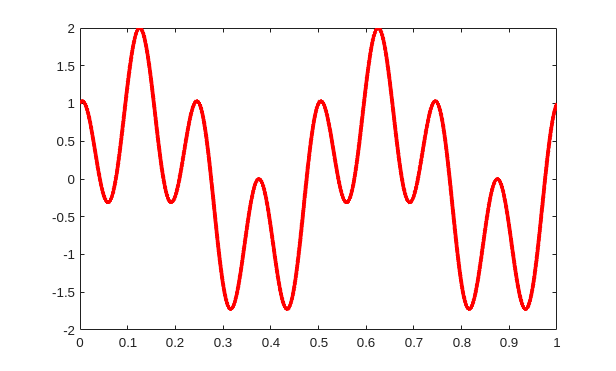

fs=5000;
t=0:(1/fs):1;
X=sin(2*pi*2*t);
Y=cos(2*pi*8*t);
s=X+Y;
plot(t, s, 'r', 'LineWidth', 3);

Funkcja findpeaks może zwracać wykres, funkcji, albo wektory, które opisują wartości szczytów i ich indeks w wektorze wejściowym s:

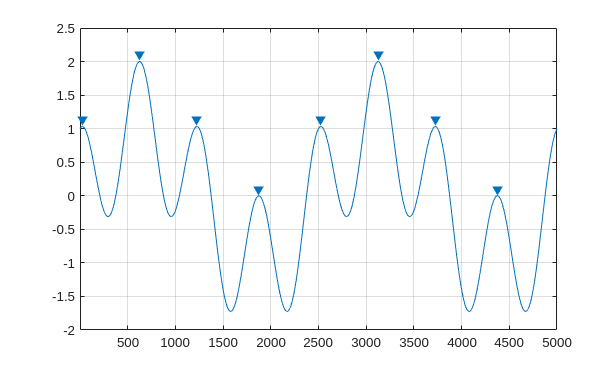

findpeaks(s)

[pks, locs] = findpeaks(s)

pks =     1.0314    2.0000    1.0314         0    1.0314    2.0000    1.0314         0


locs =           26         626        1226        1876        2526        3126        3726        4376


## Zad 13

Kolejny przyklad użycia funkcji findpeaks:

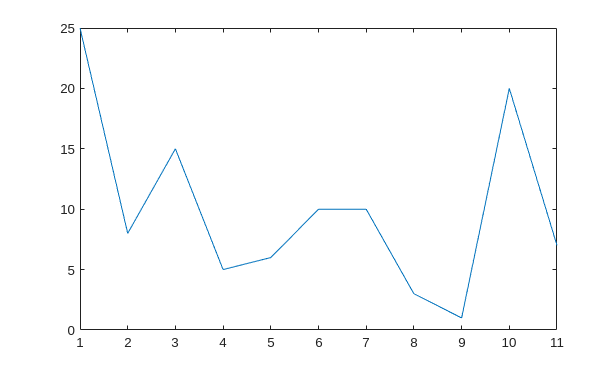

s = [25 8 15 5 6 10 10 3 1 20 7];
plot(s)

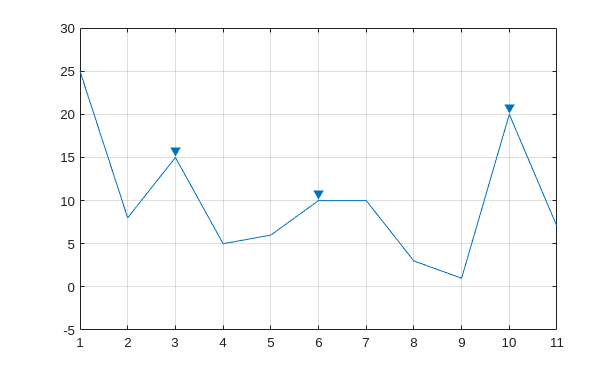

findpeaks(s)

## Zad 14

Znalezienie maksimów lokalnych i ponumerowanie ich w kolejności malejącej

s = [25 8 15 5 6 10 10 3 1 20 7];
plot(s)


[PEAKS_s, lokalizacja]= findpeaks(s, 'SortStr','descend')

PEAKS_s =     20    15    10


lokalizacja =     10     3     6


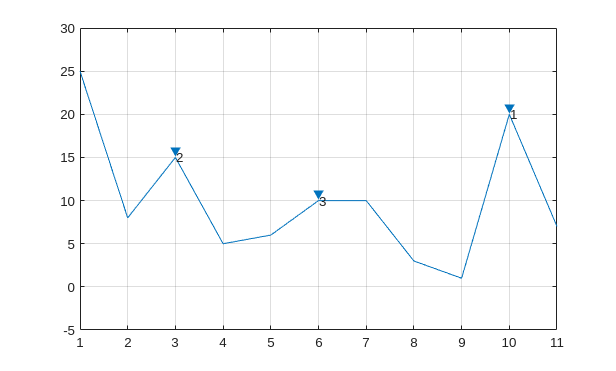

findpeaks(s, 'SortStr','descend')
text(lokalizacja +.02, PEAKS_s,num2str((1:numel(PEAKS_s))'))

## Zad 15

x= [1, 2, 3,4,5,6,7,8,9,10,11];
s = [25 8 15 5 6 10 10 3 1 20 7];
plot(x,s)

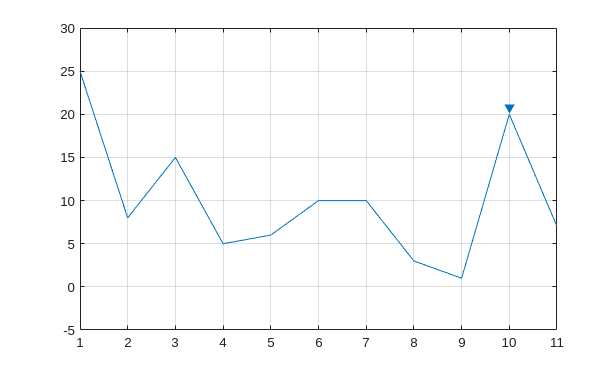

findpeaks(s, Threshold=10)

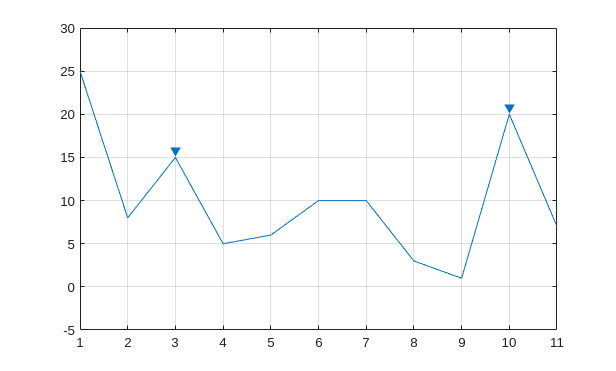

findpeaks(s, Threshold=5)

findpeaks(s, Threshold=0)

Parametr Threshold sprawia, że zeby dany punkt został uznany szczyt, to musi mieć wartośc większą o conajmniej wartość Thresholdu od swoich sąsiadów. 

## Zad 16

x= [1, 2, 3,4,5,6,7,8,9,10,11];
s = [25 8 15 5 6 10 10 3 1 20 7];
plot(x,s)

findpeaks(s, MinPeakHeight=12)

findpeaks(s, MinPeakHeight=8)

findpeaks(s, MinPeakHeight=3)

Parametr MinPeakHeight, określa, że za szczyt może zostać uznany tylko taki punkt, którego wartość jest większa od tej zdefiniowanej w parametrze.

## Zad 17

x= [1, 2, 3,4,5,6,7,8,9,10,11]

x =      1     2     3     4     5     6     7     8     9    10    11


s = [25 8 15 5 6 10 10 3 1 20 7];
plot(x,s)

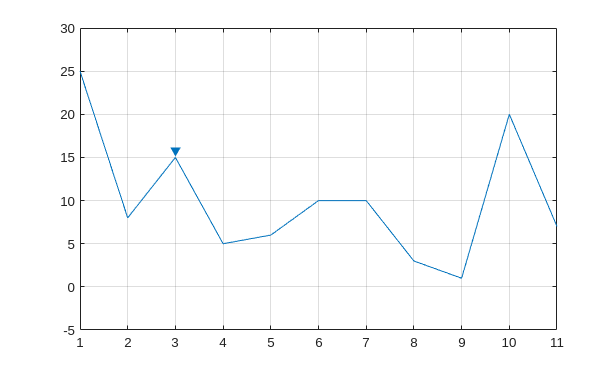

findpeaks(s, Npeaks=1)

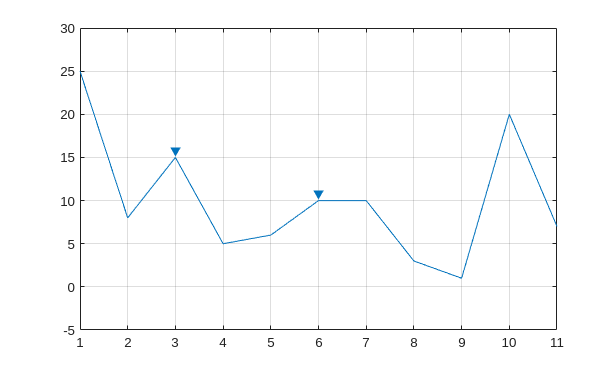

findpeaks(s, Npeaks=2)

Parametr Npeaks określa liczbę szczytów, które zostaną wykryte idąc od początku wektora przechowującego dany sygnał.

## Zad 18

x= [1, 2, 3,4,5,6,7,8,9,10,11]

x =      1     2     3     4     5     6     7     8     9    10    11


s = [25 8 15 5 6 10 10 3 1 20 7];
plot(x,s)

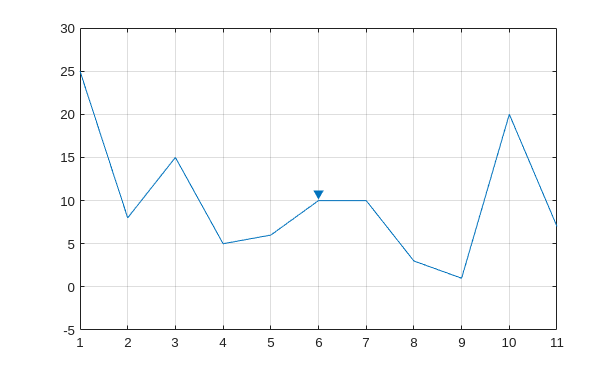

findpeaks(s, MinPeakWidth=1)

Parametr MinPeakWIdth określa, że aby dany punkt został uznany za szczyt, to musi być conajmniej o szerokości 1 próbki.

## Zad 19

Wczytywanie danych:

[wiatrak_20, fs] = audioread("pliki_wav/wiatrak_20.wav");
[przekladnia_20, fs] = audioread("pliki_wav/przekladnia20.wav");
[wiatrak_21, fs] = audioread("pliki_wav/wiatrak_21.wav");
[przekladnia_21, fs] = audioread("pliki_wav/przekladnia21.wav");

[wiatrak_23, fs] = audioread("pliki_wav/wiatrak_23.wav");
[przekladnia_23, fs] = audioread("pliki_wav/przekladnia23.wav");
[wiatrak_24, fs] = audioread("pliki_wav/wiatrak_24.wav");
[przekladnia_24, fs] = audioread("pliki_wav/przekladnia24.wav");


wiatraki = [wiatrak_20, wiatrak_21, wiatrak_23, wiatrak_24];

przekladnie = [przekladnia_20, przekladnia_21 przekladnia_23, przekladnia_24];
sygnaly_wzorcowe = [wiatrak_20, wiatrak_21, przekladnia_20, przekladnia_21];
sygnaly_testowane = [wiatrak_23, wiatrak_24, przekladnia_23, przekladnia_24];

Obliczanie RMS sygnałów

RMS_wiatraki = rms(wiatraki)

RMS_wiatraki =     0.1855    0.1823    0.1787    0.1846


RMS_przekladnie = rms(przekladnie)

RMS_przekladnie =     0.1415    0.1417    0.1469    0.1450


RMS_sygnaly_wzorcowe = rms(sygnaly_wzorcowe)

RMS_sygnaly_wzorcowe =     0.1855    0.1823    0.1415    0.1417


RMS_sygnaly_testowane = rms(sygnaly_testowane)

RMS_sygnaly_testowane =     0.1787    0.1846    0.1469    0.1450


sygnaly_wzorc_labels = ["Wiatrak 20", "Wiatrak 21","Przekładnia 20", "Przekładnia 21"];
sygnaly_test_labels = ["Wiatrak 23", "Wiatrak 24","Przekładnia 23", "Przekładnia 24"];

for i =1:length(sygnaly_test_labels)
    diff = abs(RMS_sygnaly_testowane(i) - RMS_sygnaly_wzorcowe);
    [M, I] = min(diff);
    texts = "Na podstawie obliczeń sygnał - '" + sygnaly_test_labels(i) +  "' najlepiej pasuje do sygnału '" + sygnaly_wzorc_labels(I) + "'," + newline +  "a ich wartość rms różni się tylko o: " + num2str(M);
    disp(texts)
end

Na podstawie obliczeń sygnał - 'Wiatrak 23' najlepiej pasuje do sygnału 'Wiatrak 21',
a ich wartość rms różni się tylko o: 0.0036448
Na podstawie obliczeń sygnał - 'Wiatrak 24' najlepiej pasuje do sygnału 'Wiatrak 20',
a ich wartość rms różni się tylko o: 0.00088342
Na podstawie obliczeń sygnał - 'Przekładnia 23' najlepiej pasuje do sygnału 'Przekładnia 21',
a ich wartość rms różni się tylko o: 0.0052709
Na podstawie obliczeń sygnał - 'Przekładnia 24' najlepiej pasuje do sygnału 'Przekładnia 21',
a ich wartość rms różni się tylko o: 0.003301


Na podstawie parametru rms przeprowadzono identyfikacjie danych próbek testowych. Można zauważyć, że przebiegła ona pomyślnie w wyniku czego rozróżniono w testowanym sygnale wiatrak od przekładni. Oczywiście jest to tylko mała próbka danych, a w realnym świecie jest ich znacznie więcej, natomiast pokazuje nam to jak dużo można wnioskować po parametrach sygnału.

## Odpowiedzi na pytania

**1) Jakie są podstawowe parametry sygnałów?** 

Podstawowymi parametrami sygnałów zajmowaliśmy się podczas dzisiejszego laboratorium i są to m.in.: wartość średnia, wartość RMS, współczynnik szczytu, współczynnik peak-to-peak, wartość maksymalna i minimalna, wariancja, odchylenie standardowe, energia sygnału dyskretnego, średnia moc sygnału dyskretnego oraz wartość RSS.

**2) Do czego mogą się przydać parametry sygnałów? Gdzie mogą być zastosowane?**

Parametry sygnałów są szczególne ważne w technice, otóż dzięki nim jesteśmy w stanie kontrolować i diagnozować wiele procesów. Wartość średnia określa składową stałą sygnału, a RMS pozwala mierzyć jego moc skuteczną, co jest istotne w systemach elektroenergetycznych i diagnostyce maszyn. Współczynniki szczytu i peak-to-peak wskazują ekstremalne wahania, przydatne w analizie drgań i wykrywaniu anomalii. Wariancja i odchylenie standardowe mierzą zmienność sygnału, co pozwala ocenić poziom szumów. Energia i moc sygnału określają ilość energii przenoszoną przez sygnał, co ma zastosowanie w systemach radarowych i przetwarzaniu obrazów. Parametr RSS jest wykorzystywany do wykrywania błędów w systemach predykcyjnych. Razem te parametry wspierają diagnostykę, kontrolę i optymalizację procesów inżynieryjnych, biomedycznych i komunikacyjnych

**3) Co by się stało gdybyśmy dodali do siebie wartości: RMS, RSS i maksymalną sygnału- y=xRMS+xRSS+xMAX. Czy taka wartość będzie dla nas użyteczna? Odpowiedź uzasadnić.**

W mojej opini dodanie tych sygnałów nie prowadzi do użytecznego rezultatu. Wszystkie te parametry odnoszą się do jednego sygnału, czyli są ze sobą powiązane. Dodatkowym czynnikiem odradzającym użycia takiego kryterium jest fakt, że wartość maksymalna odnosi się do jednej próbki sygnału, która z pewnych przyczyn technicznych może być znacznie zakłamana, podczas, gdy wartość RMS i RSS do całego sygnału, który analizujemy. Suma ta też nie ma interpretacji fizycznej, ponieważ nie odnosi się ani do energii sygnału, ani do mocy, błędu ani tym podobnych.

**4) Co takiego robi funkcja findpeaks()?**

Funkcja *findpeaks()* znajduje maksima lokalne w danym wektorze, który tej funkcji podamy. Na wyjściu z funkcji oprócz ich wartości otrzymujemy indeks póbki z wektora wejściowego. Dzięki możliwości skonfigurowania wielu parametrów możemy zmienić maksima, które nas interesują, np. określić minimalny poziom dla którego dana próbka może być uznana za maksimum. Dzięki tej funkcji można identyfikować zdarzenia w sygnale.

## Wnioski

Na podstawie przeprowadzonych eksperymentów można stwierdzić, że parametry sygnałów pozwalają na kompleksową analizę i identyfikację sygnałów. Obliczone wartości średnie, wariancje, odchylenia standardowe oraz wskaźniki takie jak RMS, peak-to-peak i współczynnik szczytu umożliwiają dokładne scharakteryzowanie sygnałów. Dzięki zastosowaniu funkcji `findpeaks` możliwe jest wykrywanie lokalnych maksimów, co ma zastosowanie w analizie drgań i identyfikacji zdarzeń w sygnałach. Eksperymenty z próbkami dźwiękowymi potwierdziły, że identyfikacja sygnałów testowych w oparciu o wartość RMS jest skuteczna. Parametry te mają szerokie zastosowanie w diagnostyce maszyn, analizie drgań, przetwarzaniu sygnałów akustycznych i elektroenergetycznych. Warto jednak pamiętać, że łączenie niektórych parametrów, jak RMS, RSS i wartości maksymalnej, nie daje użytecznych wyników ze względu na różne interpretacje fizyczne tych wartości.